clear all

% Read it
report = readmatrix("Cubesat Connection (Epoch Seconds).xlsx");

% Remove header row
report([1],:) = [];

% Remove each column except the access start and access end
report(:,[1,4]) = [];

## Start parsing

% Get one long list to indicate coverage per second (1 for yes, 0 for no)
accesses = length(report);
seconds_in_interval = report(accesses,2); % Get the time of the end of the last access
coverage_per_second = zeros(round(seconds_in_interval),1); % Start by making a huge list of zeros

% For each row in the access report, 
for i = 1:accesses
    
    % Get the start and end time
    curr_start = report(i,1);
    curr_end = report(i,2);
    
    % Round them to get indices for the coverage_per_second list
    start_idx = floor(curr_start+1);
    end_idx = floor(curr_end+1);
    
    % Change all values in coverage_per_second between start_idx and
    % end_idx to 1 (aka it is connected)
    coverage_per_second([start_idx:end_idx]) = 1;
end

% truncate the length so its divisible by 5400
coverage_per_second(length(coverage_per_second):5097600) = [0];

## Divide up into orbits

min orbit time is 90 min

seconds_per_orbit = 90*60;
coverage_per_orbit = reshape(coverage_per_second,seconds_per_orbit,[]); % Makes a matrix where each column represents and orbit
coverage_per_orbit = sum(coverage_per_orbit, 1); % Sum each column
min_coverage_per_orbit = min(coverage_per_orbit)

min_coverage_per_orbit = 738


mean = mean(coverage_per_orbit);
max = max(coverage_per_orbit,[],'all');
min = min(coverage_per_orbit,[],'all')

min = 738

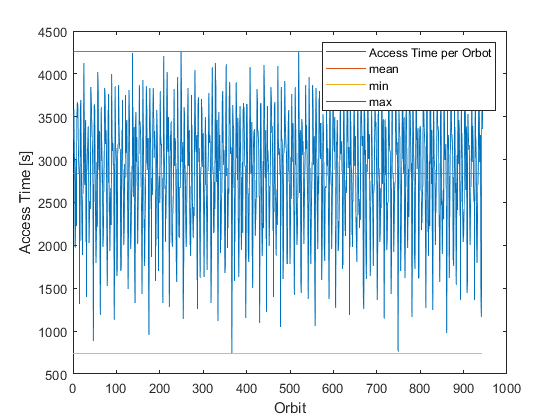


% Get the data to the right
plot(coverage_per_orbit)
hold on
plot(mean.*ones(1,944))
plot(min.*ones(1,944))
plot(max.*ones(1,944))
xlabel('Orbit')
ylabel('Access Time [s]')
legend('Access Time per Orbot', 'mean', 'min', 'max')
hold off

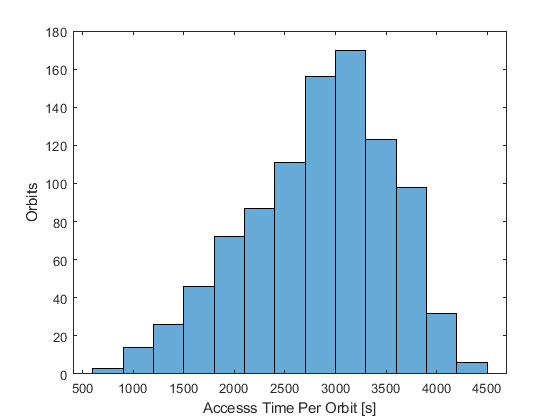


histogram(coverage_per_orbit)
xlabel('Accesss Time Per Orbit [s]');
ylabel('Orbits')


required = 1617;
below_required = coverage_per_orbit(coverage_per_orbit<1617)

below_required =         1319        1404         885        1197        1525        1134        1491        1325        1428         950        1590        1328        1280        1571        1143        1594        1258        1325        1118         738        1589        1151        1511        1102        1225        1399        1058        1604        1430        1574        1443        1377        1062        1605        1379        1273        1198        1377        1264        1608        1362        1149        1434         763        1163        1616        1275        1251        1576         981


fail_percent = size(below_required,2)/944*100

fail_percent = 6.0381

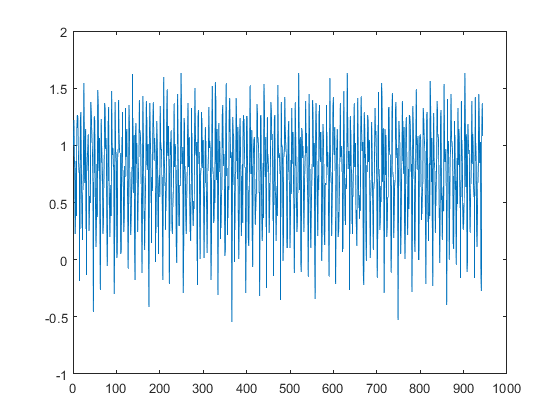

margin = (coverage_per_orbit-required)./required;
plot(margin)

## Make file for simulink

simfile = reshape(coverage_per_second,seconds_per_orbit,[]);
for col=1:944
    connect_count = 0;
    for row=1:5400
        if simfile(row,col) == 1
            connect_count = connect_count + 1;
        end
        if connect_count == 738
            simfile(row:5400, col) = 0;
            break
        end
    end
end

connect_count = 1

connect_count = 2

connect_count = 3

connect_count = 4

connect_count = 5

connect_count = 6

connect_count = 7

connect_count = 8

connect_count = 9

connect_count = 10

connect_count = 11

connect_count = 12

connect_count = 13

connect_count = 14

connect_count = 15

connect_count = 16

connect_count = 17

connect_count = 18

connect_count = 19

connect_count = 20

connect_count = 21

connect_count = 22

connect_count = 23

connect_count = 24

connect_count = 25

connect_count = 26

connect_count = 27

connect_count = 28

connect_count = 29

connect_count = 30

connect_count = 31

connect_count = 32

connect_count = 33

connect_count = 34

connect_count = 35

connect_count = 36

connect_count = 37

connect_count = 38

connect_count = 39

connect_count = 40

connect_count = 41

connect_count = 42

connect_count = 43

connect_count = 44

connect_count = 45

connect_count = 46

connect_count = 47

connect_count = 48

connect_count = 49

connect_count = 50

connect_count = 51

connect_count = 52

connect_count = 53

connect_count = 54

connect_count = 55

connect_count = 56

connect_count = 57

connect_count = 58

connect_count = 59

connect_count = 60

connect_count = 61

connect_count = 62

connect_count = 63

connect_count = 64

connect_count = 65

connect_count = 66

connect_count = 67

connect_count = 68

connect_count = 69

connect_count = 70

connect_count = 71

connect_count = 72

connect_count = 73

connect_count = 74

connect_count = 75

connect_count = 76

connect_count = 77

connect_count = 78

connect_count = 79

connect_count = 80

connect_count = 81

connect_count = 82

connect_count = 83

connect_count = 84

connect_count = 85

connect_count = 86

connect_count = 87

connect_count = 88

connect_count = 89

connect_count = 90

connect_count = 91

connect_count = 92

connect_count = 93

connect_count = 94

connect_count = 95

connect_count = 96

connect_count = 97

connect_count = 98

connect_count = 99

connect_count = 100

connect_count = 101

connect_count = 102

connect_count = 103

connect_count = 104

connect_count = 105

connect_count = 106

connect_count = 107

connect_count = 108

connect_count = 109

connect_count = 110

connect_count = 111

connect_count = 112

connect_count = 113

connect_count = 114

connect_count = 115

connect_count = 116

connect_count = 117

connect_count = 118

connect_count = 119

connect_count = 120

connect_count = 121

connect_count = 122

connect_count = 123

connect_count = 124

connect_count = 125

connect_count = 126

connect_count = 127

connect_count = 128

connect_count = 129

connect_count = 130

connect_count = 131

connect_count = 132

connect_count = 133

connect_count = 134

connect_count = 135

connect_count = 136

connect_count = 137

connect_count = 138

connect_count = 139

connect_count = 140

connect_count = 141

connect_count = 142

connect_count = 143

connect_count = 144

connect_count = 145

connect_count = 146

connect_count = 147

connect_count = 148

connect_count = 149

connect_count = 150

connect_count = 151

connect_count = 152

connect_count = 153

connect_count = 154

connect_count = 155

connect_count = 156

connect_count = 157

connect_count = 158

connect_count = 159

connect_count = 160

connect_count = 161

connect_count = 162

connect_count = 163

connect_count = 164

connect_count = 165

connect_count = 166

connect_count = 167

connect_count = 168

connect_count = 169

connect_count = 170

connect_count = 171

connect_count = 172

connect_count = 173

connect_count = 174

connect_count = 175

connect_count = 176

connect_count = 177

connect_count = 178

connect_count = 179

connect_count = 180

connect_count = 181

connect_count = 182

connect_count = 183

connect_count = 184

connect_count = 185

connect_count = 186

connect_count = 187

connect_count = 188

connect_count = 189

connect_count = 190

connect_count = 191

connect_count = 192

connect_count = 193

connect_count = 194

connect_count = 195

connect_count = 196

connect_count = 197

connect_count = 198

connect_count = 199

connect_count = 200

connect_count = 201

connect_count = 202

connect_count = 203

connect_count = 204

connect_count = 205

connect_count = 206

connect_count = 207

connect_count = 208

connect_count = 209

connect_count = 210

connect_count = 211

connect_count = 212

connect_count = 213

connect_count = 214

connect_count = 215

connect_count = 216

connect_count = 217

connect_count = 218

connect_count = 219

connect_count = 220

connect_count = 221

connect_count = 222

connect_count = 223

connect_count = 224

connect_count = 225

connect_count = 226

connect_count = 227

connect_count = 228

connect_count = 229

connect_count = 230

connect_count = 231

connect_count = 232

connect_count = 233

connect_count = 234

connect_count = 235

connect_count = 236

connect_count = 237

connect_count = 238

connect_count = 239

connect_count = 240

connect_count = 241

connect_count = 242

connect_count = 243

connect_count = 244

connect_count = 245

connect_count = 246

connect_count = 247

connect_count = 248

connect_count = 249

connect_count = 250

connect_count = 251

connect_count = 252

connect_count = 253

connect_count = 254

connect_count = 255

connect_count = 256

connect_count = 257

connect_count = 258

connect_count = 259

connect_count = 260

connect_count = 261

connect_count = 262

connect_count = 263

connect_count = 264

connect_count = 265

connect_count = 266

connect_count = 267

connect_count = 268

connect_count = 269

connect_count = 270

connect_count = 271

connect_count = 272

connect_count = 273

connect_count = 274

connect_count = 275

connect_count = 276

connect_count = 277

connect_count = 278

connect_count = 279

connect_count = 280

connect_count = 281

connect_count = 282

connect_count = 283

connect_count = 284

connect_count = 285

connect_count = 286

connect_count = 287

connect_count = 288

connect_count = 289

connect_count = 290

connect_count = 291

connect_count = 292

connect_count = 293

connect_count = 294

connect_count = 295

connect_count = 296

connect_count = 297

connect_count = 298

connect_count = 299

connect_count = 300

connect_count = 301

connect_count = 302

connect_count = 303

connect_count = 304

connect_count = 305

connect_count = 306

connect_count = 307

connect_count = 308

connect_count = 309

connect_count = 310

connect_count = 311

connect_count = 312

connect_count = 313

connect_count = 314

connect_count = 315

connect_count = 316

connect_count = 317

connect_count = 318

connect_count = 319

connect_count = 320

connect_count = 321

connect_count = 322

connect_count = 323

connect_count = 324

connect_count = 325

connect_count = 326

connect_count = 327

connect_count = 328

connect_count = 329

connect_count = 330

connect_count = 331

connect_count = 332

connect_count = 333

connect_count = 334

connect_count = 335

connect_count = 336

connect_count = 337

connect_count = 338

connect_count = 339

connect_count = 340

connect_count = 341

connect_count = 342

connect_count = 343

connect_count = 344

connect_count = 345

connect_count = 346

connect_count = 347

connect_count = 348

connect_count = 349

connect_count = 350

connect_count = 351

connect_count = 352

connect_count = 353

connect_count = 354

connect_count = 355

connect_count = 356

connect_count = 357

connect_count = 358

connect_count = 359

connect_count = 360

connect_count = 361

connect_count = 362

connect_count = 363

connect_count = 364

connect_count = 365

connect_count = 366

connect_count = 367

connect_count = 368

connect_count = 369

connect_count = 370

connect_count = 371

connect_count = 372

connect_count = 373

connect_count = 374

connect_count = 375

connect_count = 376

connect_count = 377

connect_count = 378

connect_count = 379

connect_count = 380

connect_count = 381

connect_count = 382

connect_count = 383

connect_count = 384

connect_count = 385

connect_count = 386

connect_count = 387

connect_count = 388

connect_count = 389

connect_count = 390

connect_count = 391

connect_count = 392

connect_count = 393

connect_count = 394

connect_count = 395

connect_count = 396

connect_count = 397

connect_count = 398

connect_count = 399

connect_count = 400

connect_count = 401

connect_count = 402

connect_count = 403

connect_count = 404

connect_count = 405

connect_count = 406

connect_count = 407

connect_count = 408

connect_count = 409

connect_count = 410

connect_count = 411

connect_count = 412

connect_count = 413

connect_count = 414

connect_count = 415

connect_count = 416

connect_count = 417

connect_count = 418

connect_count = 419

connect_count = 420

connect_count = 421

connect_count = 422

connect_count = 423

connect_count = 424

connect_count = 425

connect_count = 426

connect_count = 427

connect_count = 428

connect_count = 429

connect_count = 430

connect_count = 431

connect_count = 432

connect_count = 433

connect_count = 434

connect_count = 435

connect_count = 436

connect_count = 437

connect_count = 438

connect_count = 439

connect_count = 440

connect_count = 441

connect_count = 442

connect_count = 443

connect_count = 444

connect_count = 445

connect_count = 446

connect_count = 447

connect_count = 448

connect_count = 449

connect_count = 450

connect_count = 451

connect_count = 452

connect_count = 453

connect_count = 454

connect_count = 455

connect_count = 456

connect_count = 457

connect_count = 458

connect_count = 459

connect_count = 460

connect_count = 461

connect_count = 462

connect_count = 463

connect_count = 464

connect_count = 465

connect_count = 466

connect_count = 467

connect_count = 468

connect_count = 469

connect_count = 470

connect_count = 471

connect_count = 472

connect_count = 473

connect_count = 474

connect_count = 475

connect_count = 476

connect_count = 477

connect_count = 478

connect_count = 479

connect_count = 480

connect_count = 481

connect_count = 482

connect_count = 483

connect_count = 484

connect_count = 485

connect_count = 486

connect_count = 487

connect_count = 488

connect_count = 489

connect_count = 490

connect_count = 491

connect_count = 492

connect_count = 493

connect_count = 494

connect_count = 495

connect_count = 496

connect_count = 497

connect_count = 498

connect_count = 499

connect_count = 500

connect_count = 501

connect_count = 502

connect_count = 503

connect_count = 504

connect_count = 505

connect_count = 506

connect_count = 507

connect_count = 508

connect_count = 509

connect_count = 510

connect_count = 511

connect_count = 512

connect_count = 513

connect_count = 514

connect_count = 515

connect_count = 516

connect_count = 517

connect_count = 518

connect_count = 519

connect_count = 520

connect_count = 521

connect_count = 522

connect_count = 523

connect_count = 524

connect_count = 525

connect_count = 526

connect_count = 527

connect_count = 528

connect_count = 529

connect_count = 530

connect_count = 531

connect_count = 532

connect_count = 533

connect_count = 534

connect_count = 535

connect_count = 536

connect_count = 537

connect_count = 538

connect_count = 539

connect_count = 540

connect_count = 541

connect_count = 542

connect_count = 543

connect_count = 544

connect_count = 545

connect_count = 546

connect_count = 547

connect_count = 548

connect_count = 549

connect_count = 550

connect_count = 551

connect_count = 552

connect_count = 553

connect_count = 554

connect_count = 555

connect_count = 556

connect_count = 557

connect_count = 558

connect_count = 559

connect_count = 560

connect_count = 561

connect_count = 562

connect_count = 563

connect_count = 564

connect_count = 565

connect_count = 566

connect_count = 567

connect_count = 568

connect_count = 569

connect_count = 570

connect_count = 571

connect_count = 572

connect_count = 573

connect_count = 574

connect_count = 575

connect_count = 576

connect_count = 577

connect_count = 578

connect_count = 579

connect_count = 580

connect_count = 581

connect_count = 582

connect_count = 583

connect_count = 584

connect_count = 585

connect_count = 586

connect_count = 587

connect_count = 588

connect_count = 589

connect_count = 590

connect_count = 591

connect_count = 592

connect_count = 593

connect_count = 594

connect_count = 595

connect_count = 596

connect_count = 597

connect_count = 598

connect_count = 599

connect_count = 600

connect_count = 601

connect_count = 602

connect_count = 603

connect_count = 604

connect_count = 605

connect_count = 606

connect_count = 607

connect_count = 608

connect_count = 609

connect_count = 610

connect_count = 611

connect_count = 612

connect_count = 613

connect_count = 614

connect_count = 615

connect_count = 616

connect_count = 617

connect_count = 618

connect_count = 619

connect_count = 620

connect_count = 621

connect_count = 622

connect_count = 623

connect_count = 624

connect_count = 625

connect_count = 626

connect_count = 627

connect_count = 628

connect_count = 629

connect_count = 630

connect_count = 631

connect_count = 632

connect_count = 633

connect_count = 634

connect_count = 635

connect_count = 636

connect_count = 637

connect_count = 638

connect_count = 639

connect_count = 640

connect_count = 641

connect_count = 642

connect_count = 643

connect_count = 644

connect_count = 645

connect_count = 646

connect_count = 647

connect_count = 648

connect_count = 649

connect_count = 650

connect_count = 651

connect_count = 652

connect_count = 653

connect_count = 654

connect_count = 655

connect_count = 656

connect_count = 657

connect_count = 658

connect_count = 659

connect_count = 660

connect_count = 661

connect_count = 662

connect_count = 663

connect_count = 664

connect_count = 665

connect_count = 666

connect_count = 667

connect_count = 668

connect_count = 669

connect_count = 670

connect_count = 671

connect_count = 672

connect_count = 673

connect_count = 674

connect_count = 675

connect_count = 676

connect_count = 677

connect_count = 678

connect_count = 679

connect_count = 680

connect_count = 681

connect_count = 682

connect_count = 683

connect_count = 684

connect_count = 685

connect_count = 686

connect_count = 687

connect_count = 688

connect_count = 689

connect_count = 690

connect_count = 691

connect_count = 692

connect_count = 693

connect_count = 694

connect_count = 695

connect_count = 696

connect_count = 697

connect_count = 698

connect_count = 699

connect_count = 700

connect_count = 701

connect_count = 702

connect_count = 703

connect_count = 704

connect_count = 705

connect_count = 706

connect_count = 707

connect_count = 708

connect_count = 709

connect_count = 710

connect_count = 711

connect_count = 712

connect_count = 713

connect_count = 714

connect_count = 715

connect_count = 716

connect_count = 717

connect_count = 718

connect_count = 719

connect_count = 720

connect_count = 721

connect_count = 722

connect_count = 723

connect_count = 724

connect_count = 725

connect_count = 726

connect_count = 727

connect_count = 728

connect_count = 729

connect_count = 730

connect_count = 731

connect_count = 732

connect_count = 733

connect_count = 734

connect_count = 735

connect_count = 736

connect_count = 737

connect_count = 738

connect_count = 1

connect_count = 2

connect_count = 3

connect_count = 4

connect_count = 5

connect_count = 6

connect_count = 7

connect_count = 8

connect_count = 9

connect_count = 10

connect_count = 11

connect_count = 12

connect_count = 13

connect_count = 14

connect_count = 15

connect_count = 16

connect_count = 17

connect_count = 18

connect_count = 19

connect_count = 20

connect_count = 21

connect_count = 22

connect_count = 23

connect_count = 24

connect_count = 25

connect_count = 26

connect_count = 27

connect_count = 28

connect_count = 29

connect_count = 30

connect_count = 31

connect_count = 32

connect_count = 33

connect_count = 34

connect_count = 35

connect_count = 36

connect_count = 37

connect_count = 38

connect_count = 39

connect_count = 40

connect_count = 41

connect_count = 42

connect_count = 43

connect_count = 44

connect_count = 45

connect_count = 46

connect_count = 47

connect_count = 48

connect_count = 49

connect_count = 50

connect_count = 51

connect_count = 52

connect_count = 53

connect_count = 54

connect_count = 55

connect_count = 56

connect_count = 57

connect_count = 58

connect_count = 59

connect_count = 60

connect_count = 61

connect_count = 62

connect_count = 63

connect_count = 64

connect_count = 65

connect_count = 66

connect_count = 67

connect_count = 68

connect_count = 69

connect_count = 70

connect_count = 71

connect_count = 72

connect_count = 73

connect_count = 74

connect_count = 75

connect_count = 76

connect_count = 77

connect_count = 78

connect_count = 79

connect_count = 80

connect_count = 81

connect_count = 82

connect_count = 83

connect_count = 84

connect_count = 85

connect_count = 86

connect_count = 87

connect_count = 88

connect_count = 89

connect_count = 90

connect_count = 91

connect_count = 92

connect_count = 93

connect_count = 94

connect_count = 95

connect_count = 96

connect_count = 97

connect_count = 98

connect_count = 99

connect_count = 100

connect_count = 101

connect_count = 102

connect_count = 103

connect_count = 104

connect_count = 105

connect_count = 106

connect_count = 107

connect_count = 108

connect_count = 109

connect_count = 110

connect_count = 111

connect_count = 112

connect_count = 113

connect_count = 114

connect_count = 115

connect_count = 116

connect_count = 117

connect_count = 118

connect_count = 119

connect_count = 120

connect_count = 121

connect_count = 122

connect_count = 123

connect_count = 124

connect_count = 125

connect_count = 126

connect_count = 127

connect_count = 128

connect_count = 129

connect_count = 130

connect_count = 131

connect_count = 132

connect_count = 133

connect_count = 134

connect_count = 135

connect_count = 136

connect_count = 137

connect_count = 138

connect_count = 139

connect_count = 140

connect_count = 141

connect_count = 142

connect_count = 143

connect_count = 144

connect_count = 145

connect_count = 146

connect_count = 147

connect_count = 148

connect_count = 149

connect_count = 150

connect_count = 151

connect_count = 152

connect_count = 153

connect_count = 154

connect_count = 155

connect_count = 156

connect_count = 157

connect_count = 158

connect_count = 159

connect_count = 160

connect_count = 161

connect_count = 162

connect_count = 163

connect_count = 164

connect_count = 165

connect_count = 166

connect_count = 167

connect_count = 168

connect_count = 169

connect_count = 170

connect_count = 171

connect_count = 172

connect_count = 173

connect_count = 174

connect_count = 175

connect_count = 176

connect_count = 177

connect_count = 178

connect_count = 179

connect_count = 180

connect_count = 181

connect_count = 182

connect_count = 183

connect_count = 184

connect_count = 185

connect_count = 186

connect_count = 187

connect_count = 188

connect_count = 189

connect_count = 190

connect_count = 191

connect_count = 192

connect_count = 193

connect_count = 194

connect_count = 195

connect_count = 196

connect_count = 197

connect_count = 198

connect_count = 199

connect_count = 200

connect_count = 201

connect_count = 202

connect_count = 203

connect_count = 204

connect_count = 205

connect_count = 206

connect_count = 207

connect_count = 208

connect_count = 209

connect_count = 210

connect_count = 211

connect_count = 212

connect_count = 213

connect_count = 214

connect_count = 215

connect_count = 216

connect_count = 217

connect_count = 218

connect_count = 219

connect_count = 220

connect_count = 221

connect_count = 222

connect_count = 223

connect_count = 224

connect_count = 225

connect_count = 226

connect_count = 227

connect_count = 228

connect_count = 229

connect_count = 230

connect_count = 231

connect_count = 232

connect_count = 233

connect_count = 234

connect_count = 235

connect_count = 236

connect_count = 237

connect_count = 238

connect_count = 239

connect_count = 240

connect_count = 241

connect_count = 242

connect_count = 243

connect_count = 244

connect_count = 245

connect_count = 246

connect_count = 247

connect_count = 248

connect_count = 249

connect_count = 250

connect_count = 251

connect_count = 252

connect_count = 253

connect_count = 254

connect_count = 255

connect_count = 256

connect_count = 257

connect_count = 258

connect_count = 259

connect_count = 260

connect_count = 261

connect_count = 262

connect_count = 263

connect_count = 264

connect_count = 265

connect_count = 266

connect_count = 267

connect_count = 268

connect_count = 269

connect_count = 270

connect_count = 271

connect_count = 272

connect_count = 273

connect_count = 274

connect_count = 275

connect_count = 276

connect_count = 277

connect_count = 278

connect_count = 279

connect_count = 280

connect_count = 281

connect_count = 282

connect_count = 283

connect_count = 284

connect_count = 285

connect_count = 286

connect_count = 287

connect_count = 288

connect_count = 289

connect_count = 290

connect_count = 291

connect_count = 292

connect_count = 293

connect_count = 294

connect_count = 295

connect_count = 296

connect_count = 297

connect_count = 298

connect_count = 299

connect_count = 300

connect_count = 301

connect_count = 302

connect_count = 303

connect_count = 304

connect_count = 305

connect_count = 306

connect_count = 307

connect_count = 308

connect_count = 309

connect_count = 310

connect_count = 311

connect_count = 312

connect_count = 313

connect_count = 314

connect_count = 315

connect_count = 316

connect_count = 317

connect_count = 318

connect_count = 319

connect_count = 320

connect_count = 321

connect_count = 322

connect_count = 323

connect_count = 324

connect_count = 325

connect_count = 326

connect_count = 327

connect_count = 328

connect_count = 329

connect_count = 330

connect_count = 331

connect_count = 332

connect_count = 333

connect_count = 334

connect_count = 335

connect_count = 336

connect_count = 337

connect_count = 338

connect_count = 339

connect_count = 340

connect_count = 341

connect_count = 342

connect_count = 343

connect_count = 344

connect_count = 345

connect_count = 346

connect_count = 347

connect_count = 348

connect_count = 349

connect_count = 350

connect_count = 351

connect_count = 352

connect_count = 353

connect_count = 354

connect_count = 355

connect_count = 356

connect_count = 357

connect_count = 358

connect_count = 359

connect_count = 360

connect_count = 361

connect_count = 362

connect_count = 363

connect_count = 364

connect_count = 365

connect_count = 366

connect_count = 367

connect_count = 368

connect_count = 369

connect_count = 370

connect_count = 371

connect_count = 372

connect_count = 373

connect_count = 374

connect_count = 375

connect_count = 376

connect_count = 377

connect_count = 378

connect_count = 379

connect_count = 380

connect_count = 381

connect_count = 382

connect_count = 383

connect_count = 384

connect_count = 385

connect_count = 386

connect_count = 387

connect_count = 388

connect_count = 389

connect_count = 390

connect_count = 391

connect_count = 392

connect_count = 393

connect_count = 394

connect_count = 395

connect_count = 396

connect_count = 397

connect_count = 398

connect_count = 399

connect_count = 400

connect_count = 401

connect_count = 402

connect_count = 403

connect_count = 404

connect_count = 405

connect_count = 406

connect_count = 407

connect_count = 408

connect_count = 409

connect_count = 410

connect_count = 411

connect_count = 412

connect_count = 413

connect_count = 414

connect_count = 415

connect_count = 416

connect_count = 417

connect_count = 418

connect_count = 419

connect_count = 420

connect_count = 421

connect_count = 422

connect_count = 423

connect_count = 424

connect_count = 425

connect_count = 426

connect_count = 427

connect_count = 428

connect_count = 429

connect_count = 430

connect_count = 431

connect_count = 432

connect_count = 433

connect_count = 434

connect_count = 435

connect_count = 436

connect_count = 437

connect_count = 438

connect_count = 439

connect_count = 440

connect_count = 441

connect_count = 442

connect_count = 443

connect_count = 444

connect_count = 445

connect_count = 446

connect_count = 447

connect_count = 448

connect_count = 449

connect_count = 450

connect_count = 451

connect_count = 452

connect_count = 453

connect_count = 454

connect_count = 455

connect_count = 456

connect_count = 457

connect_count = 458

connect_count = 459

connect_count = 460

connect_count = 461

connect_count = 462

connect_count = 463

connect_count = 464

connect_count = 465

connect_count = 466

connect_count = 467

connect_count = 468

connect_count = 469

connect_count = 470

connect_count = 471

connect_count = 472

connect_count = 473

connect_count = 474

connect_count = 475

connect_count = 476

connect_count = 477

connect_count = 478

connect_count = 479

connect_count = 480

connect_count = 481

connect_count = 482

connect_count = 483

connect_count = 484

connect_count = 485

connect_count = 486

connect_count = 487

connect_count = 488

connect_count = 489

connect_count = 490

connect_count = 491

connect_count = 492

connect_count = 493

connect_count = 494

connect_count = 495

connect_count = 496

connect_count = 497

connect_count = 498

connect_count = 499

connect_count = 500

connect_count = 501

connect_count = 502

connect_count = 503

connect_count = 504

connect_count = 505

connect_count = 506

connect_count = 507

connect_count = 508

connect_count = 509

connect_count = 510

connect_count = 511

connect_count = 512

connect_count = 513

connect_count = 514

connect_count = 515

connect_count = 516

connect_count = 517

connect_count = 518

connect_count = 519

connect_count = 520

connect_count = 521

connect_count = 522

connect_count = 523

connect_count = 524

connect_count = 525

connect_count = 526

connect_count = 527

connect_count = 528

connect_count = 529

connect_count = 530

connect_count = 531

connect_count = 532

connect_count = 533

connect_count = 534

connect_count = 535

connect_count = 536

connect_count = 537

connect_count = 538

connect_count = 539

connect_count = 540

connect_count = 541

connect_count = 542

connect_count = 543

connect_count = 544

connect_count = 545

connect_count = 546

connect_count = 547

connect_count = 548

connect_count = 549

connect_count = 550

connect_count = 551

connect_count = 552

connect_count = 553

connect_count = 554

connect_count = 555

connect_count = 556

connect_count = 557

connect_count = 558

connect_count = 559

connect_count = 560

connect_count = 561

connect_count = 562

connect_count = 563

connect_count = 564

connect_count = 565

connect_count = 566

connect_count = 567

connect_count = 568

connect_count = 569

connect_count = 570

connect_count = 571

connect_count = 572

connect_count = 573

connect_count = 574

connect_count = 575

connect_count = 576

connect_count = 577

connect_count = 578

connect_count = 579

connect_count = 580

connect_count = 581

connect_count = 582

connect_count = 583

connect_count = 584

connect_count = 585

connect_count = 586

connect_count = 587

connect_count = 588

connect_count = 589

connect_count = 590

connect_count = 591

connect_count = 592

connect_count = 593

connect_count = 594

connect_count = 595

connect_count = 596

connect_count = 597

connect_count = 598

connect_count = 599

connect_count = 600

connect_count = 601

connect_count = 602

connect_count = 603

connect_count = 604

connect_count = 605

connect_count = 606

connect_count = 607

connect_count = 608

connect_count = 609

connect_count = 610

connect_count = 611

connect_count = 612

connect_count = 613

connect_count = 614

connect_count = 615

connect_count = 616

connect_count = 617

connect_count = 618

connect_count = 619

connect_count = 620

connect_count = 621

connect_count = 622

connect_count = 623

connect_count = 624

connect_count = 625

connect_count = 626

connect_count = 627

connect_count = 628

connect_count = 629

connect_count = 630

connect_count = 631

connect_count = 632

connect_count = 633

connect_count = 634

connect_count = 635

connect_count = 636

connect_count = 637

connect_count = 638

connect_count = 639

connect_count = 640

connect_count = 641

connect_count = 642

connect_count = 643

connect_count = 644

connect_count = 645

connect_count = 646

connect_count = 647

connect_count = 648

connect_count = 649

connect_count = 650

connect_count = 651

connect_count = 652

connect_count = 653

connect_count = 654

connect_count = 655

connect_count = 656

connect_count = 657

connect_count = 658

connect_count = 659

connect_count = 660

connect_count = 661

connect_count = 662

connect_count = 663

connect_count = 664

connect_count = 665

connect_count = 666

connect_count = 667

connect_count = 668

connect_count = 669

connect_count = 670

connect_count = 671

connect_count = 672

connect_count = 673

connect_count = 674

connect_count = 675

connect_count = 676

connect_count = 677

connect_count = 678

connect_count = 679

connect_count = 680

connect_count = 681

connect_count = 682

connect_count = 683

connect_count = 684

connect_count = 685

connect_count = 686

connect_count = 687

connect_count = 688

connect_count = 689

connect_count = 690

connect_count = 691

connect_count = 692

connect_count = 693

connect_count = 694

connect_count = 695

connect_count = 696

connect_count = 697

connect_count = 698

connect_count = 699

connect_count = 700

connect_count = 701

connect_count = 702

connect_count = 703

connect_count = 704

connect_count = 705

connect_count = 706

connect_count = 707

connect_count = 708

connect_count = 709

connect_count = 710

connect_count = 711

connect_count = 712

connect_count = 713

connect_count = 714

connect_count = 715

connect_count = 716

connect_count = 717

connect_count = 718

connect_count = 719

connect_count = 720

connect_count = 721

connect_count = 722

connect_count = 723

connect_count = 724

connect_count = 725

connect_count = 726

connect_count = 727

connect_count = 728

connect_count = 729

connect_count = 730

connect_count = 731

connect_count = 732

connect_count = 733

connect_count = 734

connect_count = 735

connect_count = 736

connect_count = 737

connect_count = 738

connect_count = 1

connect_count = 2

connect_count = 3

connect_count = 4

connect_count = 5

connect_count = 6

connect_count = 7

connect_count = 8

connect_count = 9

connect_count = 10

connect_count = 11

connect_count = 12

connect_count = 13

connect_count = 14

connect_count = 15

connect_count = 16

connect_count = 17

connect_count = 18

connect_count = 19

connect_count = 20

connect_count = 21

connect_count = 22

connect_count = 23

connect_count = 24

connect_count = 25

connect_count = 26

connect_count = 27

connect_count = 28

connect_count = 29

connect_count = 30

connect_count = 31

connect_count = 32

connect_count = 33

connect_count = 34

connect_count = 35

connect_count = 36

connect_count = 37

connect_count = 38

connect_count = 39

connect_count = 40

connect_count = 41

connect_count = 42

connect_count = 43

connect_count = 44

connect_count = 45

connect_count = 46

connect_count = 47

connect_count = 48

connect_count = 49

connect_count = 50

connect_count = 51

connect_count = 52

connect_count = 53

connect_count = 54

connect_count = 55

connect_count = 56

connect_count = 57

connect_count = 58

connect_count = 59

connect_count = 60

connect_count = 61

connect_count = 62

connect_count = 63

connect_count = 64

connect_count = 65

connect_count = 66

connect_count = 67

connect_count = 68

connect_count = 69

connect_count = 70

connect_count = 71

connect_count = 72

connect_count = 73

connect_count = 74

connect_count = 75

connect_count = 76

connect_count = 77

connect_count = 78

connect_count = 79

connect_count = 80

connect_count = 81

connect_count = 82

connect_count = 83

connect_count = 84

connect_count = 85

connect_count = 86

connect_count = 87

connect_count = 88

connect_count = 89

connect_count = 90

connect_count = 91

connect_count = 92

connect_count = 93

connect_count = 94

connect_count = 95

connect_count = 96

connect_count = 97

connect_count = 98

connect_count = 99

connect_count = 100

connect_count = 101

connect_count = 102

connect_count = 103

connect_count = 104

connect_count = 105

connect_count = 106

connect_count = 107

connect_count = 108

connect_count = 109

connect_count = 110

connect_count = 111

connect_count = 112

connect_count = 113

connect_count = 114

connect_count = 115

connect_count = 116

connect_count = 117

connect_count = 118

connect_count = 119

connect_count = 120

connect_count = 121

connect_count = 122

connect_count = 123

connect_count = 124

connect_count = 125

connect_count = 126

connect_count = 127

connect_count = 128

connect_count = 129

connect_count = 130

connect_count = 131

connect_count = 132

connect_count = 133

connect_count = 134

connect_count = 135

connect_count = 136

connect_count = 137

connect_count = 138

connect_count = 139

connect_count = 140

connect_count = 141

connect_count = 142

connect_count = 143

connect_count = 144

connect_count = 145

connect_count = 146

connect_count = 147

connect_count = 148

connect_count = 149

connect_count = 150

connect_count = 151

connect_count = 152

connect_count = 153

connect_count = 154

connect_count = 155

connect_count = 156

connect_count = 157

connect_count = 158

connect_count = 159

connect_count = 160

connect_count = 161

connect_count = 162

connect_count = 163

connect_count = 164

connect_count = 165

connect_count = 166

connect_count = 167

connect_count = 168

connect_count = 169

connect_count = 170

connect_count = 171

connect_count = 172

connect_count = 173

connect_count = 174

connect_count = 175

connect_count = 176

connect_count = 177

connect_count = 178

connect_count = 179

connect_count = 180

connect_count = 181

connect_count = 182

connect_count = 183

connect_count = 184

connect_count = 185

connect_count = 186

connect_count = 187

connect_count = 188

connect_count = 189

connect_count = 190

connect_count = 191

connect_count = 192

connect_count = 193

connect_count = 194

connect_count = 195

connect_count = 196

connect_count = 197

connect_count = 198

connect_count = 199

connect_count = 200

connect_count = 201

connect_count = 202

connect_count = 203

connect_count = 204

connect_count = 205

connect_count = 206

connect_count = 207

connect_count = 208

connect_count = 209

connect_count = 210

connect_count = 211

connect_count = 212

connect_count = 213

connect_count = 214

connect_count = 215

connect_count = 216

connect_count = 217

connect_count = 218

connect_count = 219

connect_count = 220

connect_count = 221

connect_count = 222

connect_count = 223

connect_count = 224

connect_count = 225

connect_count = 226

connect_count = 227

connect_count = 228

connect_count = 229

connect_count = 230

connect_count = 231

connect_count = 232

connect_count = 233

connect_count = 234

connect_count = 235

connect_count = 236

connect_count = 237

connect_count = 238

connect_count = 239

connect_count = 240

connect_count = 241

connect_count = 242

connect_count = 243

connect_count = 244

connect_count = 245

connect_count = 246

connect_count = 247

connect_count = 248

connect_count = 249

connect_count = 250

connect_count = 251

connect_count = 252

connect_count = 253

connect_count = 254

connect_count = 255

connect_count = 256

connect_count = 257

connect_count = 258

connect_count = 259

connect_count = 260

connect_count = 261

connect_count = 262

connect_count = 263

connect_count = 264

connect_count = 265

connect_count = 266

connect_count = 267

connect_count = 268

connect_count = 269

connect_count = 270

connect_count = 271

connect_count = 272

connect_count = 273

connect_count = 274

connect_count = 275

connect_count = 276

connect_count = 277

connect_count = 278

connect_count = 279

connect_count = 280

connect_count = 281

connect_count = 282

connect_count = 283

connect_count = 284

connect_count = 285

connect_count = 286

connect_count = 287

connect_count = 288

connect_count = 289

connect_count = 290

connect_count = 291

connect_count = 292

connect_count = 293

connect_count = 294

connect_count = 295

connect_count = 296

connect_count = 297

connect_count = 298

connect_count = 299

connect_count = 300

connect_count = 301

connect_count = 302

connect_count = 303

connect_count = 304

connect_count = 305

connect_count = 306

connect_count = 307

connect_count = 308

connect_count = 309

connect_count = 310

connect_count = 311

connect_count = 312

connect_count = 313

connect_count = 314

connect_count = 315

connect_count = 316

connect_count = 317

connect_count = 318

connect_count = 319

connect_count = 320

connect_count = 321

connect_count = 322

connect_count = 323

connect_count = 324

connect_count = 325

connect_count = 326

connect_count = 327

connect_count = 328

connect_count = 329

connect_count = 330

connect_count = 331

connect_count = 332

connect_count = 333

connect_count = 334

connect_count = 335

connect_count = 336

connect_count = 337

connect_count = 338

connect_count = 339

connect_count = 340

connect_count = 341

connect_count = 342

connect_count = 343

connect_count = 344

connect_count = 345

connect_count = 346

connect_count = 347

connect_count = 348

connect_count = 349

connect_count = 350

connect_count = 351

connect_count = 352

connect_count = 353

connect_count = 354

connect_count = 355

connect_count = 356

connect_count = 357

connect_count = 358

connect_count = 359

connect_count = 360

connect_count = 361

connect_count = 362

connect_count = 363

connect_count = 364

connect_count = 365

connect_count = 366

connect_count = 367

connect_count = 368

connect_count = 369

connect_count = 370

connect_count = 371

connect_count = 372

connect_count = 373

connect_count = 374

connect_count = 375

connect_count = 376

connect_count = 377

connect_count = 378

connect_count = 379

connect_count = 380

connect_count = 381

connect_count = 382

connect_count = 383

connect_count = 384

connect_count = 385

connect_count = 386

connect_count = 387

connect_count = 388

connect_count = 389

connect_count = 390

connect_count = 391

connect_count = 392

connect_count = 393

connect_count = 394

connect_count = 395

connect_count = 396

connect_count = 397

connect_count = 398

connect_count = 399

connect_count = 400

connect_count = 401

connect_count = 402

connect_count = 403

connect_count = 404

connect_count = 405

connect_count = 406

connect_count = 407

connect_count = 408

connect_count = 409

connect_count = 410

connect_count = 411

connect_count = 412

connect_count = 413

connect_count = 414

connect_count = 415

connect_count = 416

connect_count = 417

connect_count = 418

connect_count = 419

connect_count = 420

connect_count = 421

connect_count = 422

connect_count = 423

connect_count = 424

connect_count = 425

connect_count = 426

connect_count = 427

connect_count = 428

connect_count = 429

connect_count = 430

connect_count = 431

connect_count = 432

connect_count = 433

connect_count = 434

connect_count = 435

connect_count = 436

connect_count = 437

connect_count = 438

connect_count = 439

connect_count = 440

connect_count = 441

connect_count = 442

connect_count = 443

connect_count = 444

connect_count = 445

connect_count = 446

connect_count = 447

connect_count = 448

connect_count = 449

connect_count = 450

connect_count = 451

connect_count = 452

connect_count = 453

connect_count = 454

connect_count = 455

connect_count = 456

connect_count = 457

connect_count = 458

connect_count = 459

connect_count = 460

connect_count = 461

connect_count = 462

connect_count = 463

connect_count = 464

connect_count = 465

connect_count = 466

connect_count = 467

connect_count = 468

connect_count = 469

connect_count = 470

connect_count = 471

connect_count = 472

connect_count = 473

connect_count = 474

connect_count = 475

connect_count = 476

connect_count = 477

connect_count = 478

connect_count = 479

connect_count = 480

connect_count = 481

connect_count = 482

connect_count = 483

connect_count = 484

connect_count = 485

connect_count = 486

connect_count = 487

connect_count = 488

connect_count = 489

connect_count = 490

connect_count = 491

connect_count = 492

connect_count = 493

connect_count = 494

connect_count = 495

connect_count = 496

connect_count = 497

connect_count = 498

connect_count = 499

connect_count = 500

connect_count = 501

connect_count = 502

connect_count = 503

connect_count = 504

connect_count = 505

connect_count = 506

connect_count = 507

connect_count = 508

connect_count = 509

connect_count = 510

connect_count = 511

connect_count = 512

connect_count = 513

connect_count = 514

connect_count = 515

connect_count = 516

connect_count = 517